# Zero-Phase Filtering

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the signal and the filter.

[whaley,fs] = audioread("./data/whalesound.wav");
n = numel(whaley);
t = (0:n-1)'/fs;
b = [0.5 0.25];
a = [1 -0.1];

This code plot the group delay.

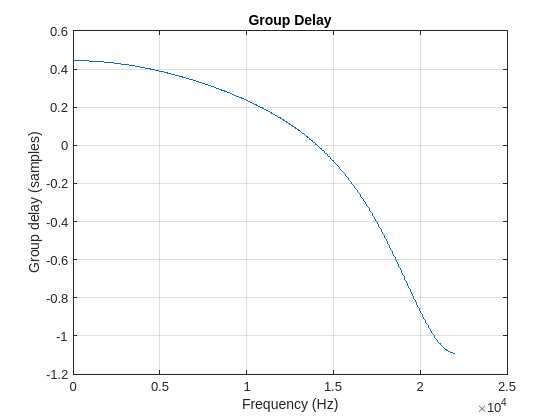

grpdelay(b,a,[],fs)

## Task 1

If your filter has constant group delay, you can remove delay by shifting the signal in time. All IIR filters, and some FIR filters, do not have linear phase, so instead, you can use a technique called [anti-causal, zero-phase filtering](https://www.mathworks.com/help/signal/ug/anti-causal-zero-phase-filter-implementation.html). The inputs and outputs are the same as with the `filter` function:

`y` `=` `filtfilt``(``b``,``a``,``x``)`

`filtfilt` will filter the signal twice, in the forward and reverse directions. This means that you need to do more processing, but the phase distortion will be eliminated.

The script contains the result of the `filter` function. Notice that the group delay is not constant, and there is some misalignment in the time-domain plot.

whalefilt = filter(b,a,whaley);
whalefilt = filtfilt(b,a,whaley);

This code compares the time-domain plots.

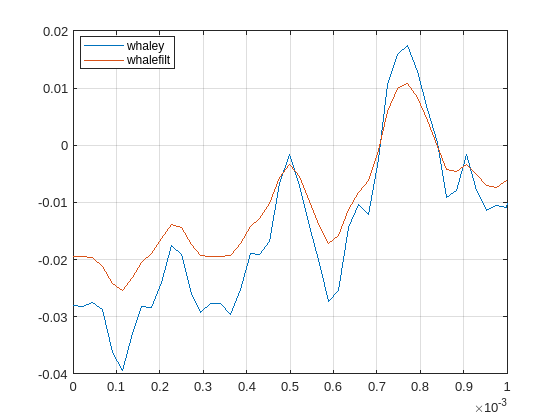

plot(t,whaley)
hold on
grid on
plot(t,whalefilt)
hold off
xlim([0 0.001])
legend(["whaley" "whalefilt"],"Location","best")